# Color from Image Segmentation

Goal: choose colors from segmented regions 

https://www.mathworks.com/help/images/marker-controlled-watershed-segmentation.html?prodcode=IP&language=en

Method:Marker-Controlled Watershed Segmentation

clear all;
close all;

## 0) Import the data

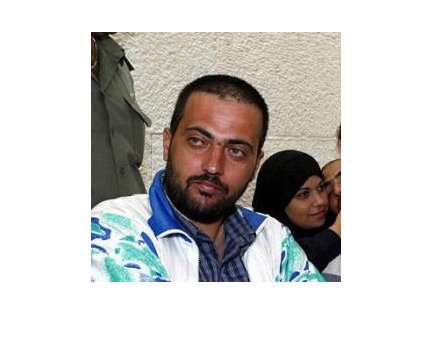

% import the data
im = im2double(imread('../lfw/Abdel_Nasser_Assidi_0002.jpg'));
%im = im2double(imread('../lfw/Avril_Lavigne_0001.jpg'));
imshow(im)

## For comparison: colors from k-means clustering

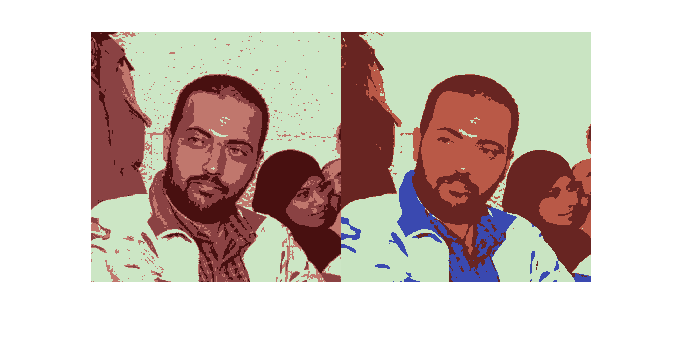

% hyperparameters
n_cluster = 4; % number of output colors
gamma = 0.5; % color adjustement
 
im_rgb = cluster_color(im, n_cluster, gamma, false);
im_lab = cluster_color(im, n_cluster, gamma, true);
imshowpair(im_rgb, im_lab, 'montage')

## Marker-Controlled Watershed Segmentation

Steps:

- Mark the Foreground Objects: with Opening-Closing by Reconstruction

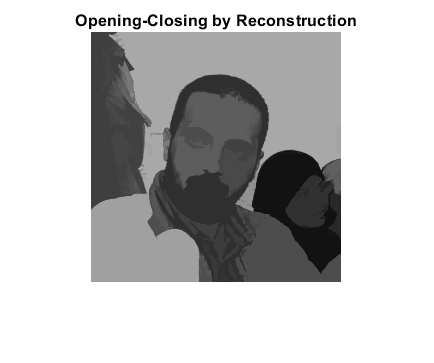

% hyperparameters
gd_thresh = 0.1; % threshold for region boundaries detection
min_edge = 50; % smallest size of edge allowed

% grayscale image
im_g = rgb2gray(im);

% smooth the image into very distinct regions
se = strel('disk', 20); % structural element
    % opening by reconstruction
im_e = imerode(im_g, se);
im_obr = imreconstruct(im_e, im_g);
    % closing by reconstruction
im_obr_d = imdilate(im_obr, se);
im_ocbr = imreconstruct(imcomplement(im_obr_d), imcomplement(im_obr));
im_ocbr = imcomplement(im_ocbr);

imshow(im_ocbr)
title('Opening-Closing by Reconstruction')

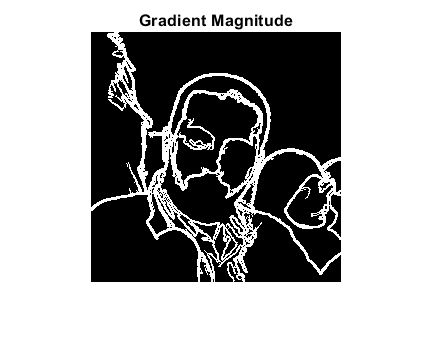


% extract the boundaries of the regions
gmag = imgradient(im_ocbr) > gd_thresh;
% filtrate small edges
gmag = bwareaopen(gmag, min_edge);

imshow(gmag)
title('Gradient Magnitude')

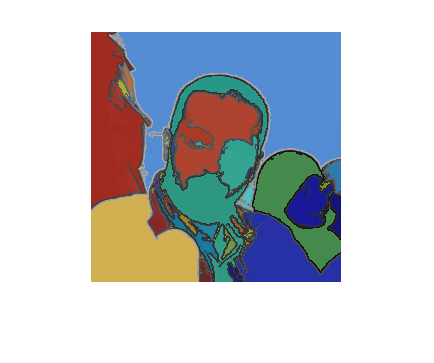


% label the regions delimited by the boundaries
[pieces_labeled, n_pieces] = bwlabel(1 - gmag);    

% display the distinct regions found
regions = labeloverlay(im_ocbr,pieces_labeled);
imshow(regions)

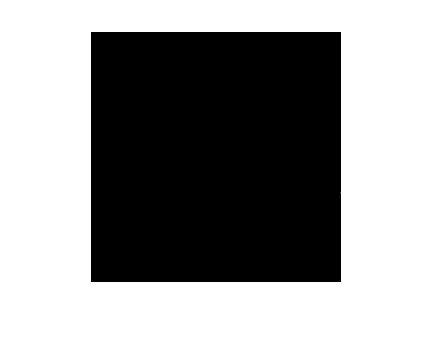


% color each region with its mean value
result = im;
for i=1 : n_pieces
    mask = pieces_labeled == i;
    n_pixel = sum(mask(:));
    mean_color = sum(reshape(im .* mask, [], 3) ,1)/n_pixel;
    result = repmat(mask, 1, 1, 3) .* reshape(mean_color, 1,1,3);
end
imshow(result)